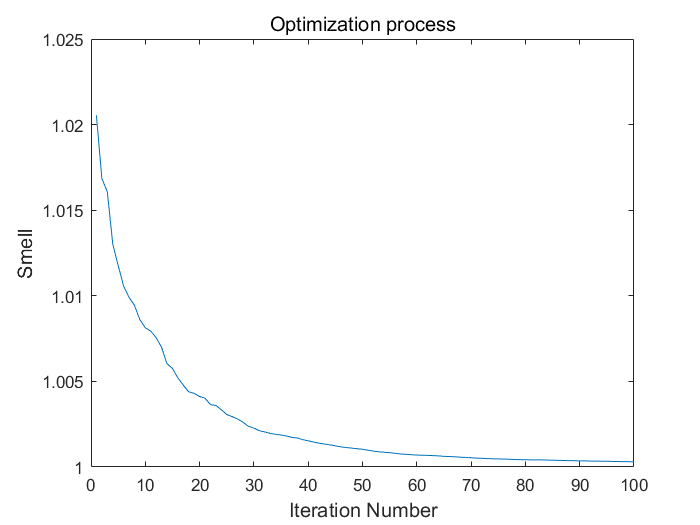

%清空
clc
clear
%随机初始果蝇群体位置
X_axis=10*rand();
Y_axis=10*rand();
%设置参数
maxgen=100; %迭代次数
sizepop=20; %种群规模
kkk=0;
%种群寻优开始，利用嗅觉寻找食物
for i=1:sizepop
for j=1:2
%附与果蝇个体利用嗅觉搜寻食物之随机方向与距离
X(i,j)=X_axis+2*rand()-1;
Y(i,j)=Y_axis+2*rand()-1;
%由于无法得知食物位置，因此先估计与原点之距离(Dist),再计算味道浓度判定值(S)，此值为距离之倒数
D(i,j)=(X(i,j)^2+Y(i,j)^2)^0.5;
S(i,j)=1/D(i,j);
end
%味道浓度判定值(S)代入味道浓度判定函数(或称为Fitness function)以求出该果蝇个体位置的味道浓度
Smell(i)=0.5+(sin((S(i,1)^2+S(i,2)^2)^0.5)^2-0.5)./(1+0.001*(S(i,1)^2+S(i,2)^2))^2;
end
%找出此果蝇群体中味道浓度最低的果蝇(求极小值)
[bestSmell bestindex]=min(Smell);
%保留最佳味道浓度值与x,y坐标，此时果蝇群体利用视觉往该位置飞去
X_axis=X(bestindex);
Y_axis=Y(bestindex);
Smellbest=bestSmell;
%果蝇迭代寻优开始
for g=1:maxgen
%附与果蝇个体利用嗅觉搜寻食物之随机方向与距离
for i=1:sizepop
%附与果蝇个体利用嗅觉搜寻食物之随机方向与距离
for j=1:2
X(i,j)=X_axis+2*rand()-1;
Y(i,j)=Y_axis+2*rand()-1;
%由于无法得知食物位置，因此先估计与原点之距离(Dist),再计算味道浓度判定值(S)，此值为距离之倒数
D(i,j)=(X(i,j)^2+Y(i,j)^2)^0.5;
S(i,j)=1/D(i,j);
end
%味道浓度判定值(S)代入味道浓度判定函数(或称为Fitness function)以求出该果蝇个体位置的味道浓度
Smell(i)=0.5+(sin((S(i,1)^2+S(i,2)^2)^0.5)^2-0.5)./(1+0.001*(S(i,1)^2+S(i,2)^2))^2+1;
end
%找出此果蝇群体中味道浓度最低的果蝇(求极小值)
[bestSmell bestindex]=min(Smell);
%判断味道浓度是否优于前一迭代味道浓度，若是则保留最佳味道浓度值与x,y坐标，此时果蝇群体利用视觉往该位置飞去
if bestSmell
kkk=kkk+1;
X_axis=X(bestindex);
Y_axis=Y(bestindex);
Smellbest=bestSmell;
end
%每代最优Smell值记录到yy数组中，并记录最优迭代坐标
yy(g)=Smellbest;
Xbest(g)=X_axis;
Ybest(g)=Y_axis;
end
%绘制迭代味道浓度与果蝇飞行路径趋势图
figure(1)
plot(yy)
title('Optimization process','fontsize',12)
xlabel('Iteration Number','fontsize',12);
ylabel('Smell','fontsize',12);

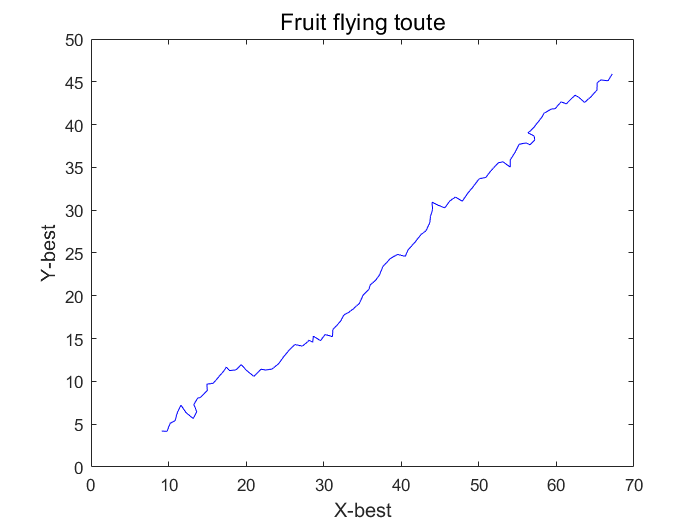

figure(2)
plot(Xbest,Ybest,'b');
title('Fruit flying toute','fontsize',14)
xlabel('X-best','fontsize',12);
ylabel('Y-best','fontsize',12);